Angel Gustavo Granados Sumalave 20191167090

Andres Camilo Lopez Bernal  20191167085

Generar n puntos aleatorios en x e y:

hold on
n = randi([1 10], 1, 1);
n1 = randi([1 10], 1, 1);
x0 = randi([-n n], n1, 1);
y0 = randi([-n1 n1], n1, 1);
x1 = randi([-n n], n1, 1);
y1 = randi([-n1 n1], n1, 1);
puntosx0y0 = [x0 y0];
puntosx1y1 = [x1 y1];


Generar pendientes de rectas

[m]=pendiente(puntosx0y0,puntosx1y1);
indeterminacion = m(:,1) == Inf | m(:,1) == -Inf | isnan(m(:,1)) | m ==0;
PosicionInd = find(indeterminacion==0);
puntosx0y0New = puntosx0y0(PosicionInd,:)

puntosx0y0New =     -6    -3
    -1     3
    -4     0


puntosx1y1New = puntosx1y1(PosicionInd,:)

puntosx1y1New =      6     1
     3     1
    -6     1


mNew = m(PosicionInd,1) 

mNew =     0.3333
   -0.5000
   -0.5000


puntosx = [ puntosx0y0New(:,1) puntosx1y1New(:,1) ];
puntosy = [ puntosx0y0New(:,2) puntosx1y1New(:,2) ];
ordenarx = [];
ordenary = [];
for i = 1:1:length(mNew)
    
    ordenarx = [ordenarx ; sort(puntosx(i,:))];
    ordenary = [ordenary ; sort(puntosy(i,:))];
end

OPX= ordenarx;
OPY= ordenary;

Intersecciones de las rectas

syms x y   
Yeqn = mNew(:,1).*x - mNew(:,1).*puntosx0y0New(:,1) + puntosx0y0New(:,2);


Xeqn = (y./mNew(:,1)) + puntosx0y0New(:,1) - (puntosx0y0New(:,2)./mNew(:,1));

EQNx_y = [Xeqn Yeqn]

$$EQNx\_y = \left(\begin{array}{cc} 3\,y+3 & \frac{x}{3}-1\\ 5-2\,y & \frac{5}{2}-\frac{x}{2}\\ -2\,y-4 & -\frac{x}{2}-2 \end{array}\right)$$


comparaYeqn =[];
comparaXeqn =[];
PunCX = [];
PunCY = [];

for i= 1:1:length(OPX(:,1))
    for j = i+1:1:length(OPX(:,1))
    
    comparaYeqn = [comparaYeqn ; Yeqn(i,1)==Yeqn(j,:)];
    PunCX= [PunCX ; vpasolve(Yeqn(i,1)==Yeqn(j,:),[OPX(i,1) OPX(i,2)])];
    
    
    comparaXeqn = [comparaXeqn ; Xeqn(i,1)==Xeqn(j,:)];
    PunCY= [PunCY ; vpasolve(Xeqn(i,1)==Xeqn(j,:), [OPY(i,1) OPY(i,2)])];
    
    
    end
end


CYeqn = comparaYeqn;
CXeqn = comparaXeqn;
PuntoCorteX = PunCX;
PuntoCorteY = PunCY;
PuntoCortesXY = [PuntoCorteX PuntoCorteY]

$$PuntoCortesXY = \left(\begin{array}{cc} 4.2 & 0.4\\ -1.2 & -1.4 \end{array}\right)$$

Gráficas de las rectas

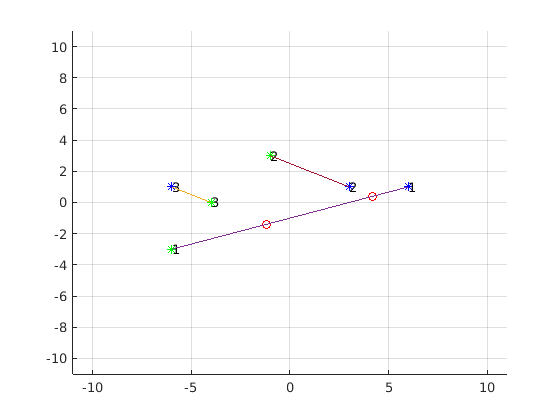

grid on

plot(PuntoCorteX,PuntoCorteY,'ro')
for i = 1:1:length(mNew(:,1))
    
    plot (puntosx0y0New(i,1), puntosx0y0New(i,2), 'g*' ) %Puntos del x0 y0
    text(puntosx0y0New(i,1), puntosx0y0New(i,2),num2str(i))
    
    plot (puntosx1y1New(i,1), puntosx1y1New(i,2), 'b*' ) %Puntos del x1 y1
    text(puntosx1y1New(i,1), puntosx1y1New(i,2),num2str(i))
    
    plot([puntosx1y1New(i,1) puntosx0y0New(i,1)],[puntosx1y1New(i,2) puntosx0y0New(i,2)]) %Grafica de la recta de los puntos
    
end

axis ([-11 11 -11 11])

hold off